# **Lab 3 - T1 2020 (Question 1)**

***by Jason Ha***

## Question 1

### Part (a)

We want the digital oscillator to be implemented per the following recursive relationship defined by the difference equation:


$$y\left\lbrack n\right\rbrack =\alpha \;y\left\lbrack n-1\right\rbrack -\beta \;y\left\lbrack n-2\right\rbrack$$


We start by recalling that an oscillator can be defined a transfer function with conjugate poles that lie on the unit circle for some frequency, $\omega =\omega_0$. Let these poles be $p_1 ,p_2$ such that:


$$p_1 ,p_2 =e^{\pm j\omega_0 }$$


Let the oscillator system be $H\left(z\right)$ in the z-domain. We can start with the following equation:


$$H\left(z\right)=\frac{1}{\left(1-p_1 z^{-1} \right)\left(1-p_2 z^{-2} \right)}=\frac{1}{1-\left(p_1 +p_2 \right)z^{-1} +p_1 p_2 z^{-2} }$$


We can see that $p_{1\;} +p_2 =2\mathrm{cos}\left(\omega_0 \right)$ and $p_1 p_2 =1$. Then, we have:


$$H\left(z\right)=\frac{1}{1-2\mathrm{cos}\left(\omega_0 \right)z^{-1} +z^{-2} }$$


If $H\left(z\right)=Y\left(z\right)/X\left(z\right)$, then we can rearrange this equation to prepare for an inverse Z-transform. This gives us:


$$Y\left(z\right)\left\lbrack 1-2\mathrm{cos}\left(\omega_0 \right)z^{-1} +z^{-2} \right\rbrack =X\left(z\right)$$



$$\Downarrow \;$$



$$y\left\lbrack n\right\rbrack -\left\lbrack 2\mathrm{cos}\left(\omega_0 \right)\right\rbrack y\left\lbrack n-1\right\rbrack +y\left\lbrack n-2\right\rbrack =x\left\lbrack n\right\rbrack$$



$$\Downarrow \;$$



$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +\left(2\mathrm{cos}\left(\omega_0 \right)\right)y\left\lbrack n-1\right\rbrack -y\left\lbrack n-2\right\rbrack$$


We need an initial excitation at $n=0$. We can let $x\left\lbrack n\right\rbrack =\mathrm{sin}\omega_0 \cdot \;\delta \;\left\lbrack n\right\rbrack$. Comparing this to the general form of the oscillator, we can see that:


$$\alpha =2\mathrm{cos}\left(\omega_0 \right)\;\;\;\;\;\mathrm{and}\;\;\;\;\;\beta =1$$


### Part (b)

The following code cell implements the oscillator via the difference equation.

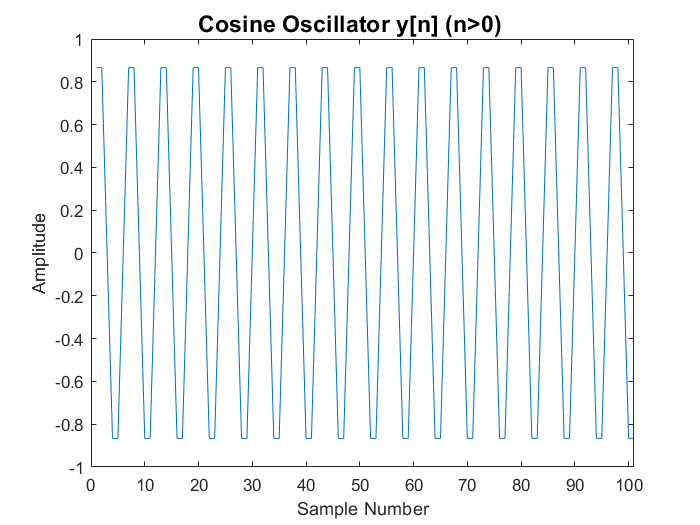

% Set the centre-frequency, w0 for the oscillator:
w0 = pi/3;

% Initiallise all necessary coefficients:
a = 2*cos(w0);
b = 1;

% Set up arrays to output:
y = zeros([100,1]);

% Plot y[n] using a for-loop:
for n = 0:length(y)
    if n == 0
        y(n+1) = sin(w0);
    elseif n==1
        y(n+1) = a*y((n+1)-1);
    else
        y(n+1) = a*y((n+1)-1) - y((n+1)-2);
    end
end

figure
plot(y)
xlim([0,length(y)])
sgtitle("Cosine Oscillator y[n] (n>0)", 'fontweight', 'bold')
xlabel("Sample Number")
ylabel("Amplitude")

### Part (c)

We now want to drive the same system using two non-zero sample values for the input. That is, we want non-zero values for $x\left\lbrack 0\right\rbrack$ and $x\left\lbrack -1\right\rbrack$ such that we can get the oscillator to produce the signal:


$$y\left\lbrack n\right\rbrack =\mathrm{sin}\left(\omega_0 n\right)$$


We can implement this 'negative' starting condition by offsetting the initial impulse to the **second** element rather than on the first element. This is shown in the code cell below:

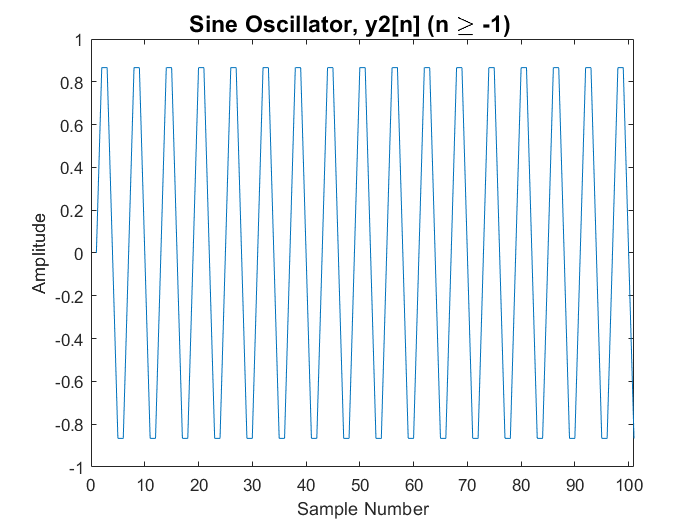

% Let y2 be the new array for this oscillator. Same size:
y2 = zeros([100, 1]);

% Plot y2[n] using this new oscillator and a modified loop condition:
for n = 0:length(y2)
    if n == 0
        y2(n+1) = 0;
    elseif n == 1
        y2(n+1) = sin(w0);
    elseif n == 2
        y2(n+1) = a*y2((n+1)-1);
    else
        y2(n+1) = a*y2((n+1)-1) - y2((n+1)-2);
    end
end

figure
plot(y2)
xlim([0,length(y2)])
sgtitle("Sine Oscillator, y2[n] (n \geq -1)", 'fontweight', 'bold')
xlabel('Sample Number')
ylabel("Amplitude")